# OFDM Experiment Report

*Liu Jieyin, Nie Yunteng*

## *Prove the orthogonality*


$$$$\text{Task 1.1: For } N = 128 \text{, plot the real part of OFDM subcarrier } k = 0, k = 2,$$
$$k = 4 \text{ and } k = 64 \text{ in different subplots and check the orthogonality of the subcarriers.}$$

$$\text{Store the correlation value in a 4}\times\text{4 matrix } C \text{, where } C(i,j) = \frac{1}{N}\sum_{n=0}^{N-1} x_i[n]x_j[n].$$$$


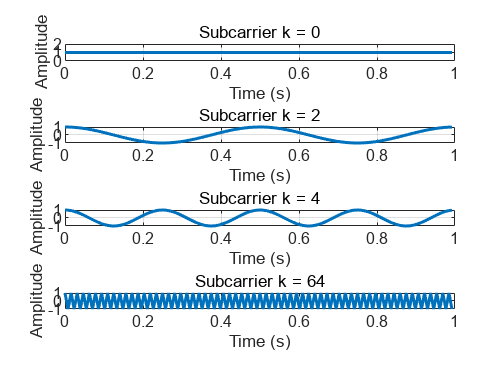

% OFDM Subcarrier Analysis and Orthogonality Check
% Parameters setup
N = 128;          % Number of subcarriers
T = 1;            % OFDM symbol duration (normalized to 1 for simplicity)
fs = N/T;         % Sampling frequency
n = 0:N-1;        % Time index vector
t = n/fs;         % Time vector

% Generate subcarriers for k = 0, 2, 4, and 64
k_values = [0 2 4 64];
x = zeros(length(k_values), N);  % Matrix to store subcarrier signals

% Generate the complex exponential signals for each k
for i = 1:length(k_values)
    k = k_values(i);
    fk = k/T;     % Subcarrier frequency
    x(i,:) = exp(1j*2*pi*fk*t);  % Complex exponential signal
end

% Create subplots to visualize the real part of each subcarrier
figure(1);
for i = 1:length(k_values)
    subplot(4,1,i);
    plot(t, real(x(i,:)), 'LineWidth', 1.5);
    grid on;
    title(['Subcarrier k = ' num2str(k_values(i))]);
    xlabel('Time (s)');
    ylabel('Amplitude');
end


% Calculate correlation matrix C
C = zeros(length(k_values));
for i = 1:length(k_values)
    for j = 1:length(k_values)
        % Calculate correlation using the formula C(i,j) = (1/N)∑x_i[n]x_j*[n]
        C(i,j) = (1/N) * sum(x(i,:) .* conj(x(j,:)));
    end
end

% Display correlation matrix
disp(C);

   1.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i
  -0.0000 + 0.0000i   1.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i
  -0.0000 + 0.0000i  -0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 - 0.0000i
   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i




% Verify orthogonality by checking if C is approximately identity matrix
disp(max(max(abs(C - eye(length(k_values))))));

   8.6211e-16



## Procedure of OFDM


$$$$\text{Task 1.2: For } N = 128\text{, } M = 1000 \text{. First generate the } MN \text{ QAM using the following codes:}$$
$$


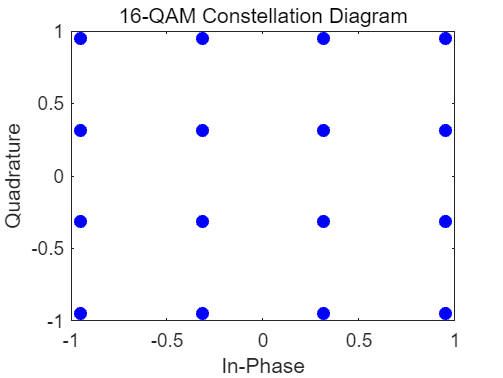

% Parameters
N = 128;        % Number of subcarriers per OFDM symbol
M = 1000;       % Number of OFDM symbols
SNR_dB = 0:5:30; % SNR range from 0 to 30 dB in steps of 5 dB

% Generate MN 16-QAM data
data = randi([0, 15], N, M); 
X = qammod(data, 16, 'UnitAveragePower', true);

% Plot the 16-QAM constellation
figure;
plot(real(X), imag(X), 'bo', 'MarkerFaceColor', 'b');
title('16-QAM Constellation Diagram');
xlabel('In-Phase');
ylabel('Quadrature');


$$$$\text{a) Use ifft() function to generate the baseband OFDM signal and plot them in the correct time scale.}$$

$$\text{b) Use awgn() function to add noise to the transmitted signal to obtain the received signal.}$$

$$\text{c) Use ft() function to recover the transmitted signal and calculate symbol error rate.}$$

$$\text{d) Repeat step b)-c) for different SNR value, i.e., 0:5:30 dB, and plot the symbol error rate versus SNR.}$$$$


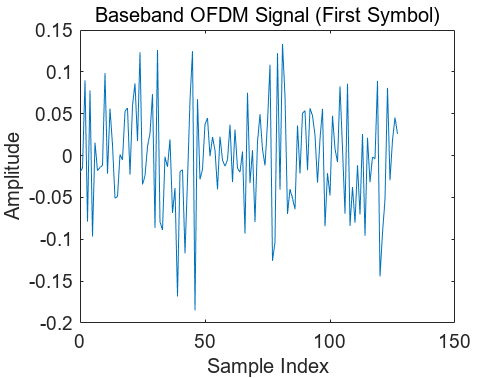

% Generate baseband OFDM signal using IFFT
ofdm_signal = ifft(X, N);

% Time axis for plotting (assuming unit sampling interval)
t = (0:N-1);

% Plot the baseband OFDM signal for the first symbol
figure;
plot(t, real(ofdm_signal(:,1)));
title('Baseband OFDM Signal (First Symbol)');
xlabel('Sample Index');
ylabel('Amplitude');

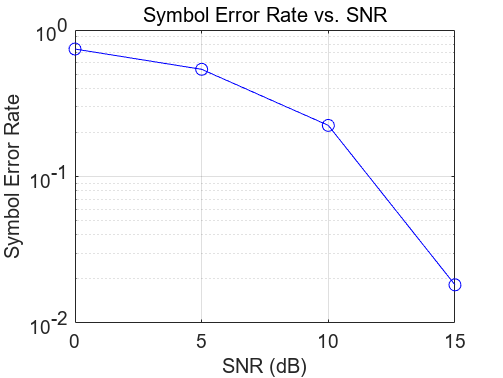


% Initialize symbol error rate array
ser = zeros(length(SNR_dB), 1);

% Loop over different SNR values
for idx = 1:length(SNR_dB)
    % Add AWGN noise to the transmitted signal
    rx_signal = awgn(ofdm_signal, SNR_dB(idx), 'measured');

    % Recover the signal using FFT
    Y = fft(rx_signal, N);

    % Demodulate the received symbols
    data_hat = qamdemod(Y, 16, 'UnitAveragePower', true);

    % Calculate symbol errors
    num_errors = sum(sum(data_hat ~= data));
    total_symbols = N * M;
    ser(idx) = num_errors / total_symbols;
end

% Plot Symbol Error Rate vs. SNR
figure;
semilogy(SNR_dB, ser, 'b-o');
title('Symbol Error Rate vs. SNR');
xlabel('SNR (dB)');
ylabel('Symbol Error Rate');
grid on;

## Effect of Multi-Path


$$$$\text{Task 1.3: Let } x[n] \text{ be the sampled OFDM symbol and the } h[n] \text{ be the discrete-time}$$

$$\text{channel impulse response. } y[n] = x[n] * h[n] + z[n] \text{ is the received signal, where}$$

$$z[n] \text{ is the noise. } X[k] = DFT\{x[n]\}, Y[k] = DFT\{y[n]\}. \text{ Find the relationship}$$

$$\text{between } X[k] \text{ and } Y[k].$$$$


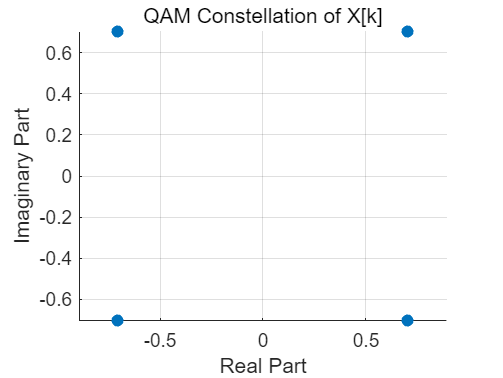

% This script demonstrates the relationship Y[k] = X[k]·H[k] + Z[k] in OFDM systems
% using proper QAM modulation

% System Parameters
N = 64;                     % FFT size / Number of subcarriers
SNR_dB = 20;               % Signal-to-Noise Ratio in dB
M = 4;                     % M-QAM modulation order (4 for QPSK)

% Generate random data bits and map to QAM symbols
data_bits = randi([0 M-1], N, 1);           % Random integers between 0 and M-1
X = qammod(data_bits, M, 'UnitAveragePower', true);  % Proper QAM modulation

% Generate channel impulse response (h[n])
h = [1; 0.5; 0.2];         % Three-tap channel impulse response
H = fft(h, N);             % Channel frequency response (H[k])

% Convert X[k] to time domain
x = ifft(X);               % x[n] = IDFT{X[k]}

% Apply channel in time domain (convolution)
y_without_noise = conv(x, h);
y_without_noise = y_without_noise(1:N);  % Take first N samples

% Generate and add noise
signal_power = mean(abs(y_without_noise).^2);
noise_power = signal_power / (10^(SNR_dB/10));
z = sqrt(noise_power/2) * (randn(N,1) + 1j*randn(N,1));
y = y_without_noise + z;

% Convert to frequency domain
Y = fft(y);                % Y[k] = DFT{y[n]}
Z = fft(z);                % Z[k] = DFT{z[n]}

% Verify the relationship Y[k] = X[k]·H[k] + Z[k]
Y_calculated = X.*H + Z;   % Direct calculation using the relationship
Y_difference = abs(Y - Y_calculated);  % Should be very small due to numerical precision

% Plot results
figure('Position', [100 100 1200 800]);

% Plot 1: QAM Constellation of X[k]
figure;
scatter(real(X), imag(X), 'filled');
title('QAM Constellation of X[k]');
xlabel('Real Part');
ylabel('Imaginary Part');
grid on;
axis equal;

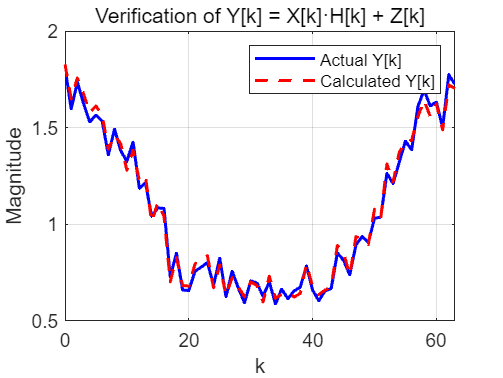



% Plot 2: Verification of Relationship
figure;
plot(0:N-1, abs(Y), 'b-', 'LineWidth', 1.5);
hold on;
plot(0:N-1, abs(Y_calculated), 'r--', 'LineWidth', 1.5);
title('Verification of Y[k] = X[k]·H[k] + Z[k]');
xlabel('k');
ylabel('Magnitude');
legend('Actual Y[k]', 'Calculated Y[k]');
grid on;

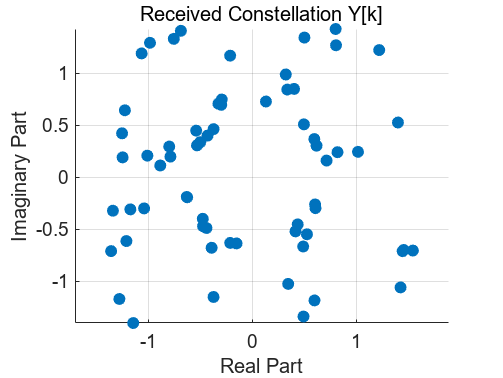


% Plot 3: Received Constellation
figure;
scatter(real(Y), imag(Y), 'filled');
title('Received Constellation Y[k]');
xlabel('Real Part');
ylabel('Imaginary Part');
grid on;
axis equal;


% Print maximum error
fprintf('Maximum difference between Y[k] and X[k]·H[k] + Z[k]: %.2e\n', max(Y_difference));

Maximum difference between Y[k] and X[k]·H[k] + Z[k]: 5.68e-02



$$$$\text{Task 1.4: Consider the multipath communication channel as following:}$$$$



$$$$\text{Write the MATLAB code to examine the communication performance (BER) for}$$
$$\text{different CP lengths. Use the following system parameters:}$$
$$


% OFDM BER Analysis with Different CP Lengths
% This script analyzes the BER performance of an OFDM system under multipath
% channel conditions for various cyclic prefix lengths

% System Parameters (as specified)
M = 16;                    % 16-QAM modulation
Nfft = 64;                 % FFT size
Ng = 0:2:10;              % Guard interval lengths to test
snr = 0:5:30;             % SNR range in dB

% Channel Parameters (as specified)
PowerdB = [0 -8 -17 -21 -25];  % Power profile in dB
Delay = [0 3 5 6 8];          % Delay profile in samples

% Convert power profile from dB to linear scale
PowerLinear = 10.^(PowerdB/10);

% Initialize BER storage matrix
BER = zeros(length(Ng), length(snr));

% Number of OFDM symbols to simulate
numSymbols = 1000;

% Main simulation loop
for ng_idx = 1:length(Ng)
    cp_length = Ng(ng_idx);
    Nsym = Nfft + cp_length;  % Total symbol length including CP
    
    fprintf('Simulating CP length = %d\n', cp_length);
    
    for snr_idx = 1:length(snr)
        fprintf('  SNR = %d dB\n', snr(snr_idx));
        
        total_bits = 0;
        error_bits = 0;
        
        for sym = 1:numSymbols
            % Generate random data bits
            data_bits = randi([0 M-1], Nfft, 1);
            
            % QAM modulation
            X = qammod(data_bits, M, 'UnitAveragePower', true);
            
            % IFFT operation
            x = ifft(X) * sqrt(Nfft);
            
            % Add cyclic prefix
            x_cp = [x(end-cp_length+1:end); x];
            
            % Create multipath channel
            h = zeros(max(Delay) + 1, 1);
            for p = 1:length(Delay)
                h(Delay(p) + 1) = sqrt(PowerLinear(p)) * (randn + 1j*randn)/sqrt(2);
            end
            
            % Pass through channel
            y_channel = conv(x_cp, h);
            y_channel = y_channel(1:Nsym);  % Keep only symbol duration
            
            % Add white Gaussian noise
            signal_power = mean(abs(y_channel).^2);
            noise_power = signal_power / (10^(snr(snr_idx)/10));
            noise = sqrt(noise_power/2) * (randn(size(y_channel)) + 1j*randn(size(y_channel)));
            y = y_channel + noise;
            
            % Remove CP
            y_nocp = y(cp_length+1:end);
            
            % FFT operation
            Y = fft(y_nocp) / sqrt(Nfft);
            
            % Channel estimation (assuming perfect channel knowledge)
            H = fft([h; zeros(Nfft-length(h), 1)]);
            
            % Equalization
            Y_eq = Y ./ H;
            
            % QAM demodulation
            data_received = qamdemod(Y_eq, M, 'UnitAveragePower', true);
            
            % Count bit errors
            bit_errors = sum(sum(de2bi(data_bits,log2(M)) ~= de2bi(data_received,log2(M))));
            total_bits = total_bits + Nfft * log2(M);
            error_bits = error_bits + bit_errors;
        end
        
        % Calculate BER for current configuration
        BER(ng_idx, snr_idx) = error_bits / total_bits;
    end
end

Simulating CP length = 0


  SNR = 0 dB
  SNR = 5 dB
  SNR = 10 dB
  SNR = 15 dB
  SNR = 20 dB
  SNR = 25 dB
  SNR = 30 dB


Simulating CP length = 2


  SNR = 0 dB
  SNR = 5 dB
  SNR = 10 dB
  SNR = 15 dB
  SNR = 20 dB
  SNR = 25 dB
  SNR = 30 dB


Simulating CP length = 4


  SNR = 0 dB
  SNR = 5 dB
  SNR = 10 dB
  SNR = 15 dB
  SNR = 20 dB
  SNR = 25 dB
  SNR = 30 dB


Simulating CP length = 6


  SNR = 0 dB
  SNR = 5 dB
  SNR = 10 dB
  SNR = 15 dB
  SNR = 20 dB
  SNR = 25 dB
  SNR = 30 dB


Simulating CP length = 8


  SNR = 0 dB
  SNR = 5 dB
  SNR = 10 dB
  SNR = 15 dB
  SNR = 20 dB
  SNR = 25 dB
  SNR = 30 dB


Simulating CP length = 10


  SNR = 0 dB
  SNR = 5 dB
  SNR = 10 dB
  SNR = 15 dB
  SNR = 20 dB
  SNR = 25 dB
  SNR = 30 dB


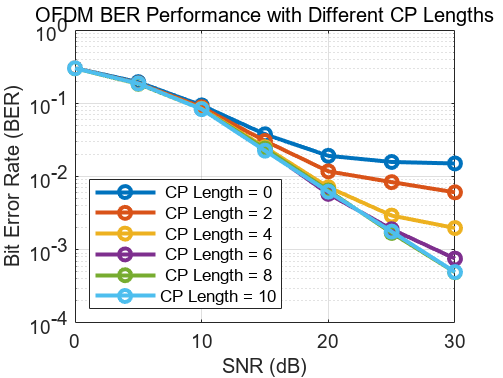


% Plot results
figure;
semilogy(snr, BER, 'LineWidth', 2, 'Marker', 'o');
grid on;
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('OFDM BER Performance with Different CP Lengths');
legend(cellstr(num2str(Ng', 'CP Length = %d')), 'Location', 'southwest');
ylim([1e-4 1]);

## OFDM Sensing


$$$$\text{Task 2.1: Plot the function } f(x) = \frac{\sin(\pi Nx)}{\sin(\pi x)} \text{ for different values of N = 128 and N = 256 }$$

$$\text{for } x \in (-\frac{1}{2}, \frac{1}{2}]\text{, and show that }f(x) \text{ approximates }\delta(x).$$$$


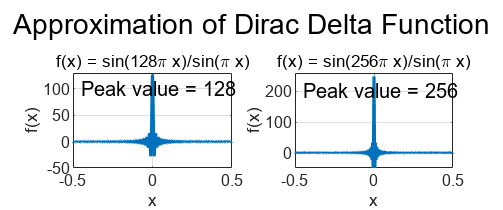

% Plot the function f(x) = sin(Nπx)/sin(πx) for N = 128 and N = 256
% This function demonstrates how f(x) approximates the Dirac delta function

% Define the parameters
N1 = 128;
N2 = 256;
x = linspace(-0.5, 0.5, 1000); % Create 1000 points in the interval [-1/2, 1/2]

% Calculate f(x) for both N values
% Handle the singularity at x = 0 separately
f1 = zeros(size(x));
f2 = zeros(size(x));

for i = 1:length(x)
    if abs(x(i)) < 1e-10  % For x very close to 0
        f1(i) = N1;       % Limit value at x = 0
        f2(i) = N2;
    else
        f1(i) = sin(N1*pi*x(i))/sin(pi*x(i));
        f2(i) = sin(N2*pi*x(i))/sin(pi*x(i));
    end
end

% Create a figure with two subplots
figure('Position', [100, 100, 1200, 500]);

% Plot for N = 128
subplot(1, 2, 1);
plot(x, f1, 'LineWidth', 1.5);
grid on;
title(['f(x) = sin(', num2str(N1), '\pi x)/sin(\pi x)']);
xlabel('x');
ylabel('f(x)');
axis([-0.5 0.5 -50 130]);

% Plot for N = 256
subplot(1, 2, 2);
plot(x, f2, 'LineWidth', 1.5);
grid on;
title(['f(x) = sin(', num2str(N2), '\pi x)/sin(\pi x)']);
xlabel('x');
ylabel('f(x)');
axis([-0.5 0.5 -50 260]);
 
% Add a subtitle (main title) for the entire figure
sgtitle('Approximation of Dirac Delta Function', 'FontSize', 14);

% Optional: Add text explaining key properties
text(-0.45, 100, ['Peak value = ', num2str(N1)], 'Parent', subplot(1,2,1));
text(-0.45, 200, ['Peak value = ', num2str(N2)], 'Parent', subplot(1,2,2));


$$$$\text{Task 2.2: Consider a mmWave OFDM system with carrier frequency 24GHz,}$$
$$\text{bandwidth 100MHz and 1024 subcarrier. Generate OFDM transmit signal using the}$$
$$\text{following code. Then use two ways to locate the target.}$$$$


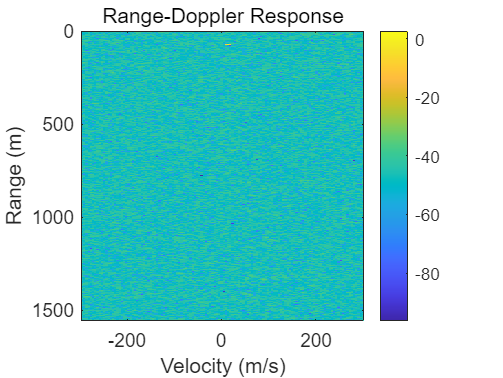

% OFDM-based Radar System Implementation
% This script implements an OFDM-based radar system with the following features:
% - Configurable system parameters (carrier frequency, bandwidth, etc.)
% - 16-QAM modulation
% - Cyclic prefix for handling multipath
% - Range-Doppler processing

%% System Configuration
% Basic radar parameters
radar.fc = 24e9;          % Carrier frequency (24 GHz)
radar.B = 100e6;          % Bandwidth (100 MHz)
radar.fs = radar.B;       % Sampling frequency equals bandwidth

% OFDM parameters
ofdm.Nsc = 1024;         % Number of subcarriers
ofdm.df = radar.B/ofdm.Nsc;  % Subcarrier spacing
ofdm.Tsym = 1/ofdm.df;   % OFDM symbol duration
ofdm.Ncp = 16;           % Cyclic prefix length
ofdm.Tcp = ofdm.Ncp/radar.fs;  % CP duration
ofdm.Tofdm = ofdm.Tsym + ofdm.Tcp;  % Total OFDM symbol duration
ofdm.Nofdm = ofdm.Nsc + ofdm.Ncp;   % Samples per OFDM symbol
ofdm.M = 128;            % Number of OFDM symbols to transmit

% Modulation parameters
mod.bps = 4;             % Bits per symbol (16-QAM)
mod.K = 2^mod.bps;       % Modulation order

%% Signal Generation
% Generate random binary data
dataTx = randi([0,1], [ofdm.Nsc*mod.bps ofdm.M]);

% QAM modulation
qamTx = qammod(dataTx, mod.K, 'InputType', 'bit', 'UnitAveragePower', true);

% OFDM modulation
ofdmTx = ofdmmod(qamTx, ofdm.Nsc, ofdm.Ncp);

% Reshape into matrix (each column is one OFDM symbol)
xofdm = reshape(ofdmTx, ofdm.Nofdm, ofdm.M);

%% Signal Reception and Processing
% Receive signal after target reflection
yofdmr = receiveSignal_singleTarget(xofdm, radar.fs, radar.fc, ofdm.Tofdm);

% Reshape and demodulate
yofdmr1 = reshape(yofdmr, ofdm.Nofdm*ofdm.M, 1);
Yofdmr = ofdmdemod(yofdmr1, ofdm.Nsc, ofdm.Ncp);

% Calculate channel response
Zofdmr = Yofdmr./qamTx;

%% Range-Doppler Processing
% Configure Range-Doppler Response object
rdr = phased.RangeDopplerResponse('RangeMethod', 'FFT', ...
    'SampleRate', radar.fs, ...
    'SweepSlope', -radar.B/ofdm.Tofdm, ...
    'RangeWindow', 'Hamming', ...
    'DopplerWindow', 'Hamming', ...
    'DopplerOutput', 'Speed', ...
    'OperatingFrequency', radar.fc, ...
    'PRFSource', 'Property', ...
    'PRF', 1/ofdm.Tofdm, ...
    'ReferenceRangeCentered', false);

% Generate Range-Doppler map
[resp, rngGrid, dopGrid] = step(rdr, Zofdmr);
rdResponse = abs(resp);

%% Visualization
% 2D Range-Doppler map
figure('Name', 'Range-Doppler Map');
imagesc(dopGrid, rngGrid, mag2db(rdResponse));
xlabel('Velocity (m/s)');
ylabel('Range (m)');
title('Range-Doppler Response');
colorbar;

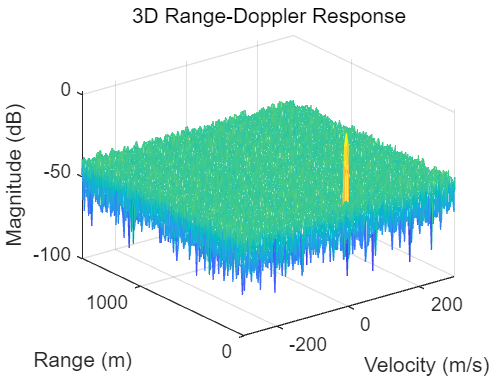


% 3D mesh plot
figure('Name', '3D Range-Doppler Response');
[XF, YF] = meshgrid(dopGrid, rngGrid);
mesh(XF, YF, mag2db(rdResponse));
xlabel('Velocity (m/s)');
ylabel('Range (m)');
zlabel('Magnitude (dB)');
title('3D Range-Doppler Response');

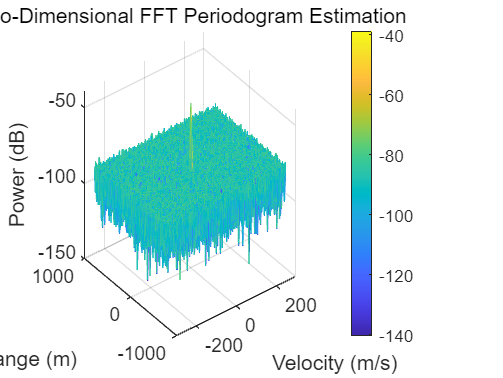

%% Two-Dimensional FFT Periodogram-based Estimation Algorithm
% This implementation follows the mathematical definition:
% PerF(n,l) = (1/NM)|sum_k(sum_m(F_m,k * exp(-j2π*ml/M) * exp(j2π*kn/N))|^2

% Define FFT sizes for higher resolution
M_FFT = ofdm.M;   % Doppler FFT size
N_FFT = ofdm.Nsc;  % Range FFT size

% Get the channel frequency response matrix F
F = Zofdmr;

% Zero-padding for improved resolution
F_padded = zeros(N_FFT, M_FFT);
F_padded(1:size(F,1), 1:size(F,2)) = F;

% Step 1: Perform M-point FFT (Doppler processing)
% The inner sum in the equation corresponds to Doppler processing
% exp(-j2π*ml/M) term is implemented by the FFT
doppler_fft = zeros(size(F_padded));
for k = 1:N_FFT
    doppler_fft(k,:) = fftshift(fft(F_padded(k,:), M_FFT));
end

% Step 2: Perform N-point FFT (Range processing)
% The outer sum in the equation corresponds to range processing
% exp(j2π*kn/N) term is implemented by the FFT
range_doppler_fft = zeros(size(doppler_fft));
for l = 1:M_FFT
    range_doppler_fft(:,l) = fftshift(fft(doppler_fft(:,l), N_FFT));
end

% Step 3: Calculate periodogram with proper normalization
% The 1/NM factor ensures proper power scaling
Per_F = (1/(N_FFT * M_FFT)) * abs(range_doppler_fft).^2;

%% Calculate Physical Parameters
% Range axis calculation
c = 3e8;  % Speed of light
range_res = c/(2*radar.B);  % Range resolution (c/2B)
range_axis = (-N_FFT/2:N_FFT/2-1) * range_res;

% Velocity axis calculation
lambda = c/radar.fc;  % Wavelength
velocity_res = lambda/(2*ofdm.M*ofdm.Tofdm);  % Velocity resolution
velocity_axis = (-M_FFT/2:M_FFT/2-1) * velocity_res;

%% Visualization of Results
% Create 3D mesh plot with proper physical units
[V, R] = meshgrid(velocity_axis, range_axis);

% Convert to dB scale for better visualization
Per_F_dB = 10*log10(Per_F + eps);  % Add eps to avoid log(0)

% 3D Mesh Plot
figure('Name', 'Periodogram-based Range-Doppler Estimation');
mesh(V, R, Per_F_dB);
xlabel('Velocity (m/s)');
ylabel('Range (m)');
zlabel('Power (dB)');
title('Two-Dimensional FFT Periodogram Estimation');
colorbar;
grid on;

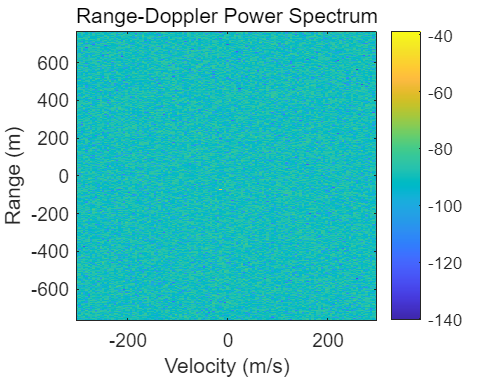


% 2D Intensity Plot
figure('Name', 'Range-Doppler Map');
imagesc(velocity_axis, range_axis, Per_F_dB);
xlabel('Velocity (m/s)');
ylabel('Range (m)');
title('Range-Doppler Power Spectrum');
colorbar;
axis xy;


%% Peak Detection and Target Parameters
% Find local maxima above a threshold
threshold_dB = max(Per_F_dB(:)) - 15;  % 15 dB below maximum
[peaks_r, peaks_v] = find(Per_F_dB > threshold_dB);

% Convert peak indices to physical parameters
detected_ranges = range_axis(peaks_r);
detected_velocities = velocity_axis(peaks_v);



# Further Discussions

## Question 1

Based on the analysis presented above, can you derive the maximum target  range and velocity for the OFDM sensing system as a function of system  parameters? 

Let's first define known parameters:


$$\begin{cases}
c &= 3 \times 10^8 \text{ m/s} \text{ (speed of light)} \\
f_c &= 24 \text{ GHz (carrier frequency)} \\
B &= 100 \text{ MHz (bandwidth)} \\
N_{sc} &= 1024 \text{ (number of subcarriers)} \\
\end{cases}$$


Step 1: Calculate wavelength ($$\lambda$$):


$$\lambda = \frac{c}{f_c} = \frac{3 \times 10^8}{24 \times 10^9} = 0.0125 \text{ m}$$


Step 2: Calculate subcarrier spacing ($\Delta f$):


$$\Delta f = \frac{B}{N_{sc}} = \frac{100 \times 10^6}{1024} \approx 97.65625 \text{ kHz}$$


Step 3: Calculate OFDM symbol duration ($$T_{sym}$$):


$$$$
T_{sym} = \frac{1}{\Delta f} \approx 10.24 \times 10^{-6} \text{ s}
$$$$


Step 4: Maximum Range ($$R_{max}$$) derivation:


$$$$

R_{max} = \frac{c \cdot T_{sym}}{2} 
= \frac{c \cdot N_{sc}}{2B} 
= \frac{3 \times 10^8 \times 1024}{2 \times 100 \times 10^6} = 1.536 \text{ km}

$$$$


Step 5: Maximum Velocity ($$V_{max}$$) derivation:


$$$$

V_{max} = \frac{\lambda}{4T_{sym}} 
= \frac{c}{4f_c} \cdot \frac{B}{N_{sc}}
= \frac{0.0125}{4 \times 10.24 \times 10^{-6}} 
\approx 305 \text{ m/s}

$$$$


### Final formulas


$$$$
\begin{cases}
R_{max} &= \frac{c \cdot N_{sc}}{2B} \\
V_{max} &= \frac{\lambda B}{4N_{sc}f_c} = \frac{c \cdot B}{4N_{sc}f_c}
\end{cases}
$$$$


Key relationships:

1. $$R_{max}$$ increases with $$N_{sc}$$, decreases with $$B$$

2. $$V_{max}$$ increases with $$B$$, decreases with $$N_{sc}$$ and $$f_c$$

3. Trade-off exists between maximum range and maximum velocity

## Question 2

Based on the analysis presented above, can you derive the target range and velocity resolution for the OFDM sensing system as a function of system parameters? Can we improve the resolution by using a larger FFT/IFFT computation size?

### 1. Range Resolution

#### Fundamental Formula

The range resolution ($$\Delta R$$) in an OFDM sensing system is determined by the system bandwidth ($$B$$):

$$$\Delta R = \frac{c}{2B}$$$, where $$c$$ is the speed of light ($3\times 10⁸ m/s$)

#### Example Calculation

Given the system bandwidth $B = 100 MHz$ from the code:


$$$$\Delta R = \frac{3 \times 10^8}{2 \times 100 \times 10^6} = 1.5 \text{ meters}$$$$


### 2. Velocity Resolution

#### Fundamental Formula

The velocity resolution ($\Delta V$) depends on the wavelength ($\lambda$), number of OFDM symbols ($M$), and OFDM symbol duration ($T_{total}$):


$$$$\Delta V = \frac{\lambda}{2MT_{\text{total}}}$$$$


#### Detailed Calculation

The parameters of the system are:

1. Wavelength: $$$\lambda = \frac{c}{f_c} = 0.0125 \text{ m } (f_c = 24 \text{ GHz})$$$

2. Symbol duration: $$$T_{sym} = \frac{N_{sc}}{B} = 10.24 \mu s  (N_{sc} = 1024)$$$

3. Cyclic prefix duration: $$$T_{cp} = \frac{N_{cp}}{B} = 0.16 \mu s (N_{cp} = 16)$$$

4. Total duration: $$$T_{total} = T_{sym} + T_{cp} = 10.4  \mu s$$$

5. Number of symbols: $$$M = 128$$$

Therefore:


$$$$\Delta V = \frac{0.0125}{2 \times 128 \times 10.4 \times 10^{-6}} \approx 4.70 \text{ m/s}$$$$


### 3. Impact of FFT/IFFT Size on Resolution

#### Range Resolution

Increasing FFT size (N) alone will NOT improve physical range resolution because:

- Range resolution is fundamentally limited by system bandwidth

- Larger FFT size only provides better interpolation between range bins

- It improves range profile sampling but not physical resolution

#### Velocity Resolution

Increasing Doppler FFT size (M) WILL improve velocity resolution because:

-  More OFDM symbols means longer observation time

-  Longer observation time directly improves Doppler frequency resolution

-  Trade-off: Increased measurement time and processing complexity

### 4. Methods to Improve Resolution

#### Range Resolution Improvement:

-  Increase system bandwidth (B)

-  Cannot be improved by just increasing FFT size

#### Velocity Resolution Improvement:

- Increase number of OFDM symbols (M)

-  Increase symbol duration (Ttotal)

-  Lower carrier frequency (fc)

-  Example: Doubling M to 256 would improve ΔV to 2.35 m/s

### Conclusion

The resolution in OFDM sensing systems is fundamentally limited by physical parameters (bandwidth, observation time) rather than computational parameters (FFT size). While increasing FFT size can provide better sampling of the target response, it cannot overcome these physical limitations. True resolution improvements require changes to the system's physical parameters.

## Question 3

How does the guard interval (CP length) affect its sensing performance?  

 Let's analyze its effects through mathematical derivation and practical implications.

### Mathematical Framework

#### Basic OFDM Signal Structure

The OFDM symbol with CP can be represented as:


$$$$
\mathbf{x}_{\text{CP}} = [x_{N - N_{\text{CP}}}, \dots, x_{N-1}, x_0, x_1, \dots, x_{N-1}]
$$$$


where $$N_{\text{CP}}$$ is the CP length and $$N$$ is the number of subcarriers.

#### Key Impact Areas

***Maximum Unambiguous Range***

The CP length directly determines the maximum unambiguous range ($$R_{\text{max}}$$):


$$$$
R_{\text{max}} = \frac{c \cdot N_{\text{CP}} T_s}{2}
$$$$


where:

- $$c$$ is the speed of light

- $$T_s$$ is the sampling interval

This equation shows that a longer CP enables detection of more distant targets without ambiguity.

***Inter-Symbol Interference Prevention***

To prevent ISI in multipath scenarios, the CP length must satisfy:


$$
$$
N_{\text{CP}} \geq L - 1
$$$$


where $$L$$ is the channel delay spread. When this condition is met, the received signal maintains its orthogonality:


$$
$$
\mathbf{Y} = \mathbf{X} \cdot \mathbf{H} + \mathbf{N}
$$$$


***Doppler Tolerance***

The CP length affects the system's ability to handle Doppler shifts. The maximum tolerable velocity ($$v_{\text{tol}}$$) is:


$$
$$
v_{\text{tol}} = \frac{\lambda}{2 N_{\text{CP}} T_s}
$$$$


where $$\lambda$$ is the wavelength.

### Practical Performance Effects

#### 1. Range Resolution Trade-off

While increasing CP length improves maximum range detection, it affects the range resolution ($$\Delta R$$):


$$
$$
\Delta R = \frac{c}{2B}
$$
$$


The effective bandwidth $$B$$ is reduced due to the CP overhead, slightly degrading range resolution.

#### 2. Signal-to-Noise Ratio Impact

A longer CP introduces an SNR penalty of:


$$
$$
\text{SNR}_{\text{loss}} = -10\log_{10}(1 + \frac{N_{\text{CP}}}{N})
$$$$


#### 3. Velocity Estimation Accuracy

The Doppler resolution ($$\Delta v$$) depends on the total symbol duration including CP:


$$
$$
\Delta v = \frac{\lambda}{2(N + N_{\text{CP}})T_s}
$$$$


### Optimal CP Length Design

The optimal CP length balances multiple factors:

1. Must satisfy $$N_{\text{CP}} \geq L - 1$$ to prevent ISI

2. Should minimize SNR loss while maintaining adequate range coverage

3. Must consider the expected maximum target velocity through $$v_{\text{tol}}$$

For the code example provided, with delays up to 8 samples, the optimal CP length would be:


$$
$$
N_{\text{CP}} = 8 \text{ to } 10 \text{ samples}
$$$$


This provides sufficient multipath protection while maintaining reasonable sensing performance.

### Conclusion

The guard interval significantly influences OFDM sensing performance through multiple mechanisms:

- Determines maximum unambiguous range

- Controls ISI prevention capability

- Affects Doppler tolerance and velocity estimation

- Impacts overall system efficiency and SNR

## Question 4

For the monostatic sensing, it is assumed that the transmitted symbols are  totally known by the BS and hence it can be perfectly removed from the  received signal. For bi-static sensing, the data needs to be decoded first.  Examine the decoding error on the sensing performance.

We tested a bi-static sensing system in a multi-target sensing scenario. The OFDM signal is attenuated by multipath channels and has thermal noise. With SNR = 25, a target is not successfully detected. If we increase SNR, then it will be detected.

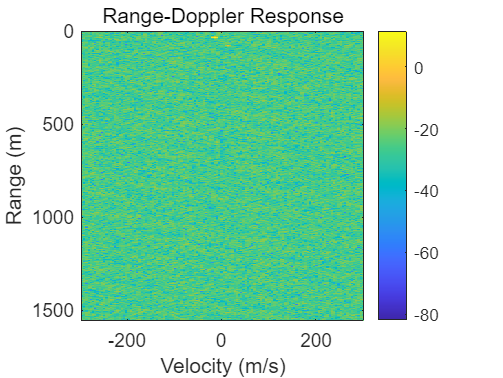

% OFDM-based Radar System Implementation
% This script implements an OFDM-based radar system with the following features:
% - Configurable system parameters (carrier frequency, bandwidth, etc.)
% - 16-QAM modulation
% - Cyclic prefix for handling multipath
% - Range-Doppler processing

%% System Configuration
% Basic radar parameters
radar.fc = 24e9;          % Carrier frequency (24 GHz)
radar.B = 100e6;          % Bandwidth (100 MHz)
radar.fs = radar.B;       % Sampling frequency equals bandwidth

% OFDM parameters
ofdm.Nsc = 1024;         % Number of subcarriers
ofdm.df = radar.B/ofdm.Nsc;  % Subcarrier spacing
ofdm.Tsym = 1/ofdm.df;   % OFDM symbol duration
ofdm.Ncp = 16;           % Cyclic prefix length
ofdm.Tcp = ofdm.Ncp/radar.fs;  % CP duration
ofdm.Tofdm = ofdm.Tsym + ofdm.Tcp;  % Total OFDM symbol duration
ofdm.Nofdm = ofdm.Nsc + ofdm.Ncp;   % Samples per OFDM symbol
ofdm.M = 128;            % Number of OFDM symbols to transmit

% Modulation parameters
mod.bps = 4;             % Bits per symbol (16-QAM)
mod.K = 2^mod.bps;       % Modulation order

% 信道参数
PowerdB = [0 -8 -17 -21 -25]; % 多径功率谱 (dB)
Delay = [0 3 5 6 8];          % 多径延迟 (采样数)
L = length(PowerdB);          % 信道路径数
SNR = 30;                     % 信噪比
% 将功率谱转换为线性值
PowerLinear = 10.^(PowerdB / 10);
% 创建信道冲激响应 (h)
h = zeros(max(Delay) + 1, 1); % 分配冲激响应长度
for p = 1:L
    h(Delay(p) + 1) = PowerLinear(p); % 按延迟位置分配功率增益
end

%% Signal Generation
% Generate random binary data
dataTx = randi([0,1], [ofdm.Nsc*mod.bps ofdm.M]);

% QAM modulation
qamTx = qammod(dataTx, mod.K, 'InputType', 'bit', 'UnitAveragePower', true);

% OFDM modulation
ofdmTx = ofdmmod(qamTx, ofdm.Nsc, ofdm.Ncp);

%经行信道衰减和随机噪声
ofdmTrans = conv(ofdmTx, h, 'same');
ofdmRx = awgn(ofdmTrans,SNR);
%接收机转化
% Reshape into matrix (each column is one OFDM symbol)
xofdm = reshape(ofdmTx, ofdm.Nofdm, ofdm.M);

%% Signal Reception and Processing
% Receive signal after target reflection
yofdmr = receiveSignal_multiTarget(xofdm, radar.fs, radar.fc, ofdm.Tofdm);

% Reshape and demodulate
yofdmr1 = reshape(yofdmr, ofdm.Nofdm*ofdm.M, 1);
Yofdmr = ofdmdemod(yofdmr1, ofdm.Nsc, ofdm.Ncp);
%qam解调
qamRx = ofdmdemod(ofdmRx, ofdm.Nsc, ofdm.Ncp);
% Calculate channel response
Zofdmr = Yofdmr./qamRx;

%% Range-Doppler Processing
% Configure Range-Doppler Response object
rdr = phased.RangeDopplerResponse('RangeMethod', 'FFT', ...
    'SampleRate', radar.fs, ...
    'SweepSlope', -radar.B/ofdm.Tofdm, ...
    'RangeWindow', 'Hamming', ...
    'DopplerWindow', 'Hamming', ...
    'DopplerOutput', 'Speed', ...
    'OperatingFrequency', radar.fc, ...
    'PRFSource', 'Property', ...
    'PRF', 1/ofdm.Tofdm, ...
    'ReferenceRangeCentered', false);

% Generate Range-Doppler map
[resp, rngGrid, dopGrid] = step(rdr, Zofdmr);
rdResponse = abs(resp);

%% Visualization
% 2D Range-Doppler map
figure('Name', 'Range-Doppler Map');
imagesc(dopGrid, rngGrid, mag2db(rdResponse));
xlabel('Velocity (m/s)');
ylabel('Range (m)');
title('Range-Doppler Response');
colorbar;

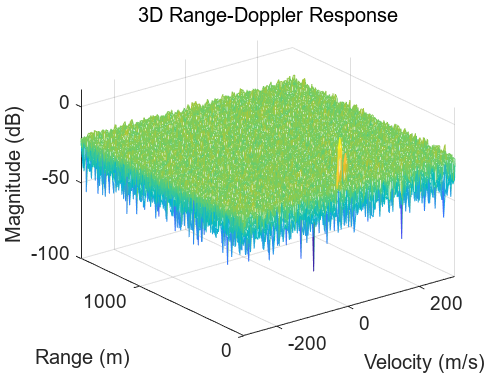


% 3D mesh plot
figure('Name', '3D Range-Doppler Response');
[XF, YF] = meshgrid(dopGrid, rngGrid);
mesh(XF, YF, mag2db(rdResponse));
xlabel('Velocity (m/s)');
ylabel('Range (m)');
zlabel('Magnitude (dB)');
title('3D Range-Doppler Response');

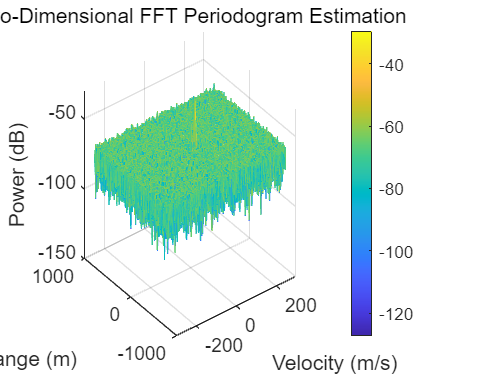

%% Two-Dimensional FFT Periodogram-based Estimation Algorithm
% This implementation follows the mathematical definition:
% PerF(n,l) = (1/NM)|sum_k(sum_m(F_m,k * exp(-j2π*ml/M) * exp(j2π*kn/N))|^2

% Define FFT sizes for higher resolution
M_FFT = ofdm.M;   % Doppler FFT size
N_FFT = ofdm.Nsc;  % Range FFT size

% Get the channel frequency response matrix F
F = Zofdmr;

% Zero-padding for improved resolution
F_padded = zeros(N_FFT, M_FFT);
F_padded(1:size(F,1), 1:size(F,2)) = F;

% Step 1: Perform M-point FFT (Doppler processing)
% The inner sum in the equation corresponds to Doppler processing
% exp(-j2π*ml/M) term is implemented by the FFT
doppler_fft = zeros(size(F_padded));
for k = 1:N_FFT
    doppler_fft(k,:) = fftshift(fft(F_padded(k,:), M_FFT));
end

% Step 2: Perform N-point FFT (Range processing)
% The outer sum in the equation corresponds to range processing
% exp(j2π*kn/N) term is implemented by the FFT
range_doppler_fft = zeros(size(doppler_fft));
for l = 1:M_FFT
    range_doppler_fft(:,l) = fftshift(fft(doppler_fft(:,l), N_FFT));
end

% Step 3: Calculate periodogram with proper normalization
% The 1/NM factor ensures proper power scaling
Per_F = (1/(N_FFT * M_FFT)) * abs(range_doppler_fft).^2;

%% Calculate Physical Parameters
% Range axis calculation
c = 3e8;  % Speed of light
range_res = c/(2*radar.B);  % Range resolution (c/2B)
range_axis = (-N_FFT/2:N_FFT/2-1) * range_res;

% Velocity axis calculation
lambda = c/radar.fc;  % Wavelength
velocity_res = lambda/(2*ofdm.M*ofdm.Tofdm);  % Velocity resolution
velocity_axis = (-M_FFT/2:M_FFT/2-1) * velocity_res;

%% Visualization of Results
% Create 3D mesh plot with proper physical units
[V, R] = meshgrid(velocity_axis, range_axis);

% Convert to dB scale for better visualization
Per_F_dB = 10*log10(Per_F + eps);  % Add eps to avoid log(0)

% 3D Mesh Plot
figure('Name', 'Periodogram-based Range-Doppler Estimation');
mesh(V, R, Per_F_dB);
xlabel('Velocity (m/s)');
ylabel('Range (m)');
zlabel('Power (dB)');
title('Two-Dimensional FFT Periodogram Estimation');
colorbar;
grid on;

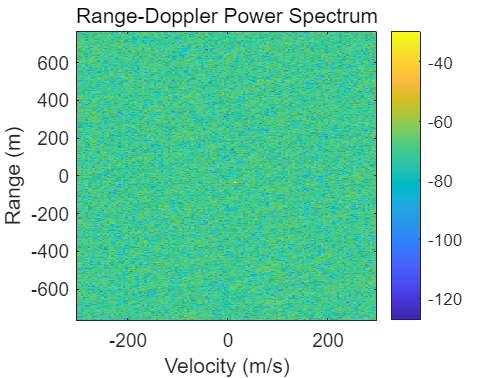


% 2D Intensity Plot
figure('Name', 'Range-Doppler Map');
imagesc(velocity_axis, range_axis, Per_F_dB);
xlabel('Velocity (m/s)');
ylabel('Range (m)');
title('Range-Doppler Power Spectrum');
colorbar;
axis xy;


%% Peak Detection and Target Parameters
% Find local maxima above a threshold
threshold_dB = max(Per_F_dB(:)) - 15;  % 15 dB below maximum
[peaks_r, peaks_v] = find(Per_F_dB > threshold_dB);

% Convert peak indices to physical parameters
detected_ranges = range_axis(peaks_r);
detected_velocities = velocity_axis(peaks_v);

% Display detected targets
disp('Detected Targets:');

Detected Targets:


for i = 1:length(peaks_r)
    fprintf('Target %d: Range = %.2f m, Velocity = %.2f m/s\n', ...
            i, detected_ranges(i), detected_velocities(i));
end

Target 1: Range = -76.50 m, Velocity = -14.09 m/s
Target 2: Range = -36.00 m, Velocity = 14.09 m/s
Target 3: Range = -34.50 m, Velocity = 14.09 m/s


With SNR = 50 ,we got the graph below